# Limb Movement Classification with EMG Data: Advanced Signal Features

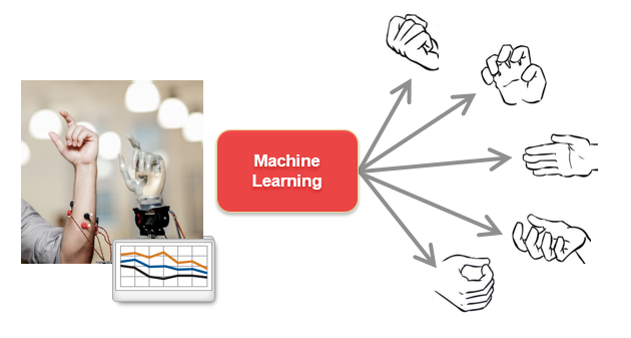

The goal of this analysis is to develop a classifier to identify type of movement from EMG signal for prosthetics development. We will process EMG sensor data with known actions, then train a classification algorithm to make predictions given new sensor readings.  

In this example, we will use more advanced signal features to better distinguish between the classes of movement.

fs = 1800; % Sensor frequency (Hz)
dt = 1/fs; % Discrete time element (s)

## Import Data

First, we need to import the data from each of the different files into one table. A convenient way to do this is with `datastore`. Datastores allow you to point at a collection of files, specify the formatting, and then read in all or a portion of the data as needed.

dataPath = pwd;
trainds = datastore(fullfile(dataPath,'Data\TrainingData\*.csv'));
trainds.SelectedFormats{9} = '%C'; % Convert labels to categorical
nsensors = 8; 
preview(trainds)

ans = 8×9 table
    rawDataOut1    rawDataOut2    rawDataOut3    rawDataOut4    rawDataOut5    rawDataOut6    rawDataOut7    rawDataOut8      Action  
    ___________    ___________    ___________    ___________    ___________    ___________    ___________    ___________    __________
       36838          37549          38656          38854          38616          38933          38893          59486       Chuck Grip
       40395          38024          38854          39723          39644          39763          39684          56561       Chuck Grip
       41344          39091          38893          40118          40395          40158          39723          49407       Chuck Grip
   

Read all of the data into one table and create a time vector for plotting.

addpath(pwd,"Supervised_wSignalProcessing/")
TrainData = readall(trainds);
t = seconds(0:dt:dt*(height(TrainData)-1))';

## Visualize Data

Visualize the signals, colored by action, in the grouped scatter plot below.

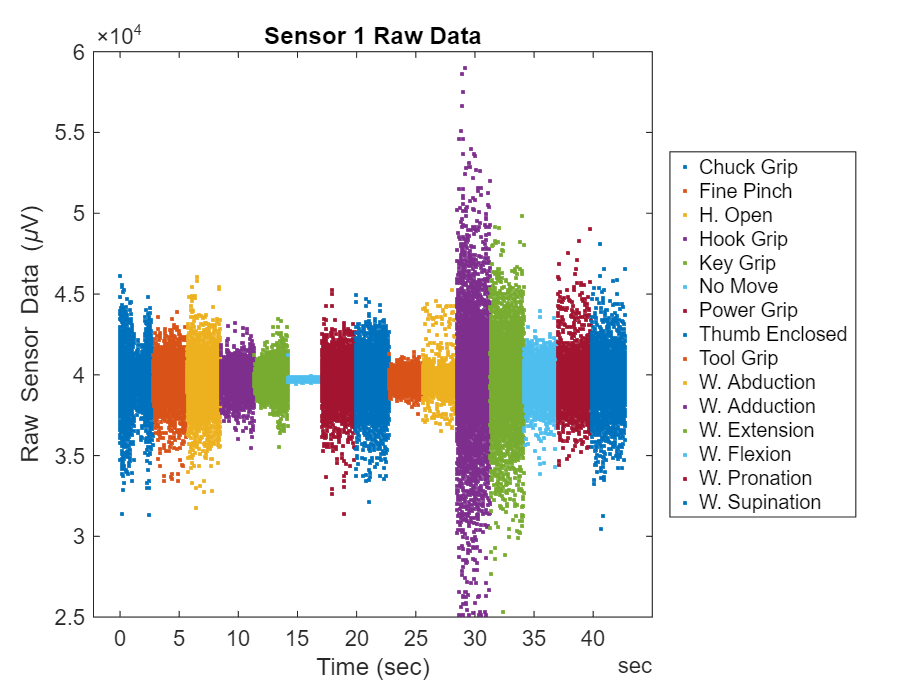

sensorNum = 1;
gscatter(t,TrainData{:,sensorNum},TrainData.Action)
title("Sensor " + num2str(sensorNum) + " Raw Data")
xlabel('Time (sec)')
ylabel('Raw Sensor Data (\muV)')
legend(categories(TrainData.Action),'Location','EastOutside')

We can also take a look at all of the channels for a single action using [`stackedplot`](matlab: web(fullfile(docroot, 'matlab/ref/stackedplot.html'))) and logical indexing.

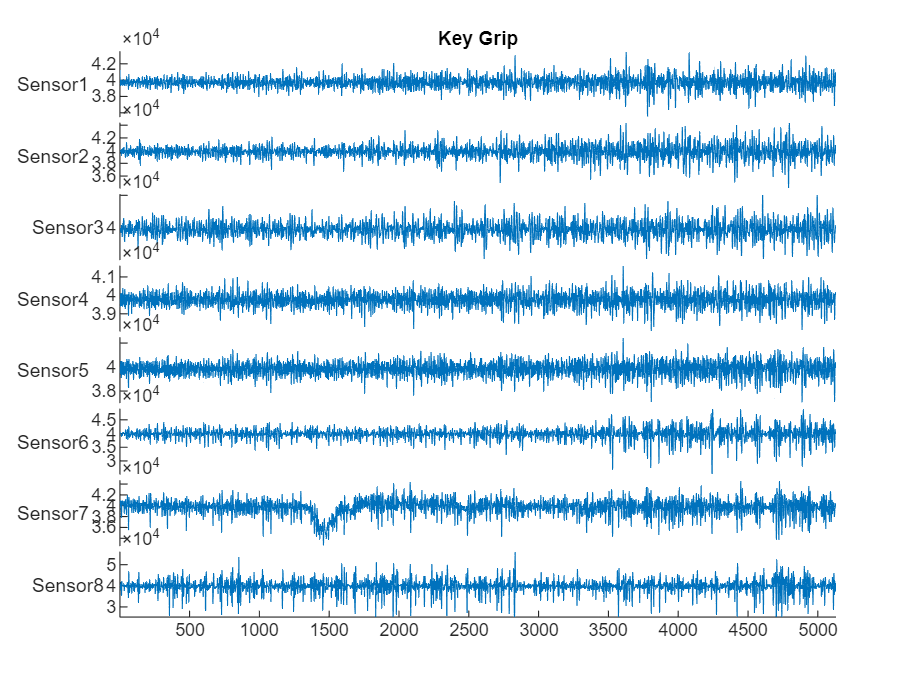

TrainDataTime = table2timetable(TrainData,'RowTimes',t);
actionToPlot = "Key Grip";
stackedplot(TrainDataTime{TrainDataTime.Action == actionToPlot, 1:8},'DisplayLabels',"Sensor" + (1:8));
title(num2str(actionToPlot))

## Preprocess Data

Preprocessing can help the classification algorithms do a better job by smoothing, transforming, or applying statistics to the original signal that are better indicators of what is happening in the data. Examining the grouped scatter plot, it appears that the variance, range, and mean of small segments might help differentiate between classes.

We also need to consider the window length when calculating statistics. Rather than using moving statistics, we will take advantage of the fact that the recorded actions require a certain number of samples so all of those adjacent points are part of the same action. To figure out how big this block should be, we will take the greatest common divisor of the number of samples per action and the sampling frequency.

naction = mode(countcats(TrainData.Action)); % Samples in most common action
blocksize = naction/gcd(naction, fs);

## Differentiating Features

We need to extract features from our data that will help our machine learning algorithm differentiate between classes. We could start by doing something very simple: calculate some basic statistics from small chunks of consecutive data, regardless of how they are distributed in time. For example, we could calculate `max`, `min`, and `std` values, and use these as features to train our machine learning algorithm.

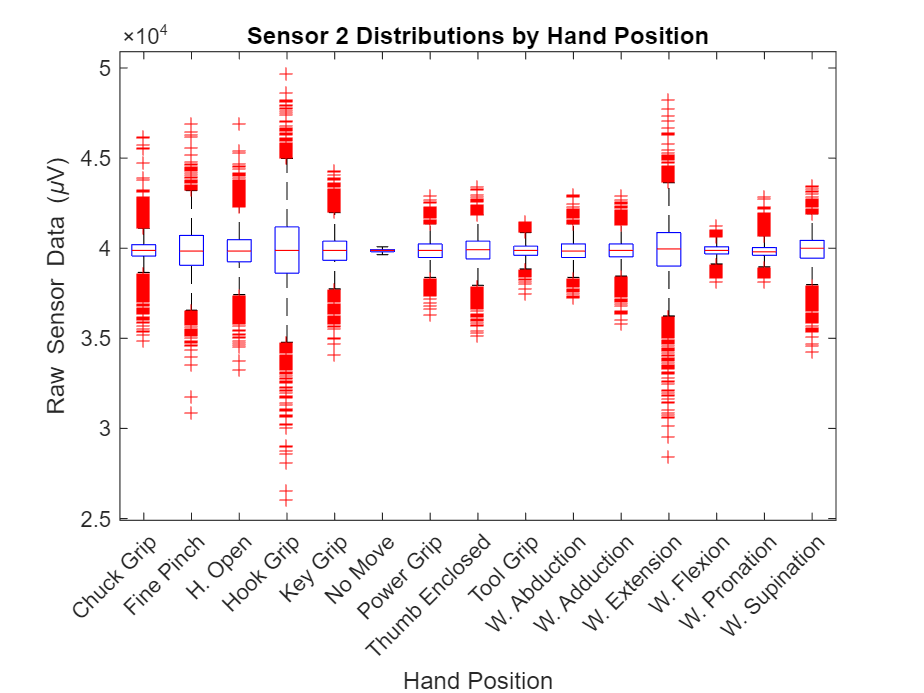

boxplot(TrainData.rawDataOut2,TrainData.Action);
a = gca;
a.XTickLabelRotation = 45;
title('Sensor 2 Distributions by Hand Position')
xlabel('Hand Position')
ylabel('Raw Sensor Data (\muV)')

## Feature Extraction Using Signal Processing

For signals that are statistically similar, it is no longer sufficient to rely on simple statistics to differentiate between the signals. This is when signal processing can play a key role. Let's first remove the DC offset and rectify the raw signal, which are common tasks in EMG processing. 

### **Remove DC Offset**

Use [`detrend`](matlab: web(fullfile(docroot, 'matlab/ref/detrend.html'))) to remove the DC offset from the EMG signal in preparation for signal processing.

data_DC = detrend(TrainData{:,1:end-1});

### **Full-Wave Rectification**

Half- or full-wave rectification is a common step in processing EMG signals. We will do this by taking the absolute value of the signal. 

rec_data = abs(data_DC);

Then visualize the rectified signal below.

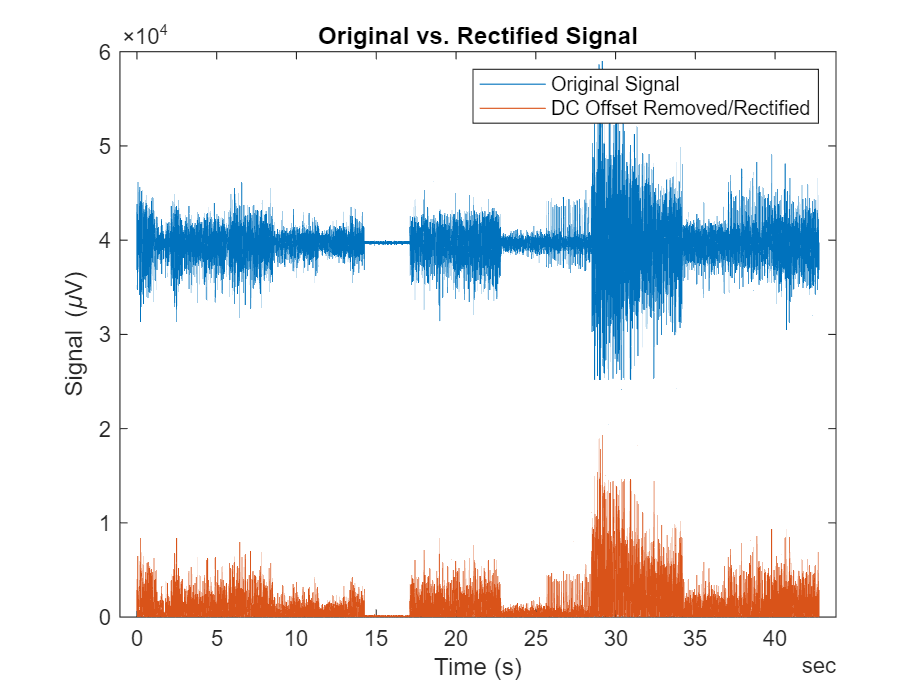

plot(t,TrainData{:,1},t,rec_data(:,1))
title('Original vs. Rectified Signal')
xlabel('Time (s)')
ylabel('Signal (\muV)')
legend('Original Signal','DC Offset Removed/Rectified')

### Signal Analyzer

Where do we find features for machine learning? There are many possible waveform parameters that can be explored and extracted. Let's use the [Signal Analyzer App](matlab: signalAnalyzer) to visualize and explore the differences between a few signals to get some ideas for differentiating between the various actions.

wsupination = data_DC(TrainData.Action == 'W. Supination',1);
keygrip = data_DC(TrainData.Action == 'Key Grip',1);
nomove = data_DC(TrainData.Action == 'No Move',1);

Open the Signal Analyzer App from the toolstrip or with the following command.

`signalAnalyzer`

### Linear Envelope

Another common approach to processing EMG signals is to take the linear envelope. Let's look at two methods for finding the linear envelope: using a low pass filter, and using RMS.

**Option 1 - Low Pass Filter **

Let's first try out the Filter Designer App to apply a low-pass filter to the rectified signal to obtain the signal envelope.

lp = LPFilter;
env1 = filter(lp,rec_data);

**Option 2 - RMS Envelope**

A common approach to obtaining the linear envelope is via RMS. 

[env2,~] = envelope(rec_data,blocksize*3,'rms');

**Plot and Compare**

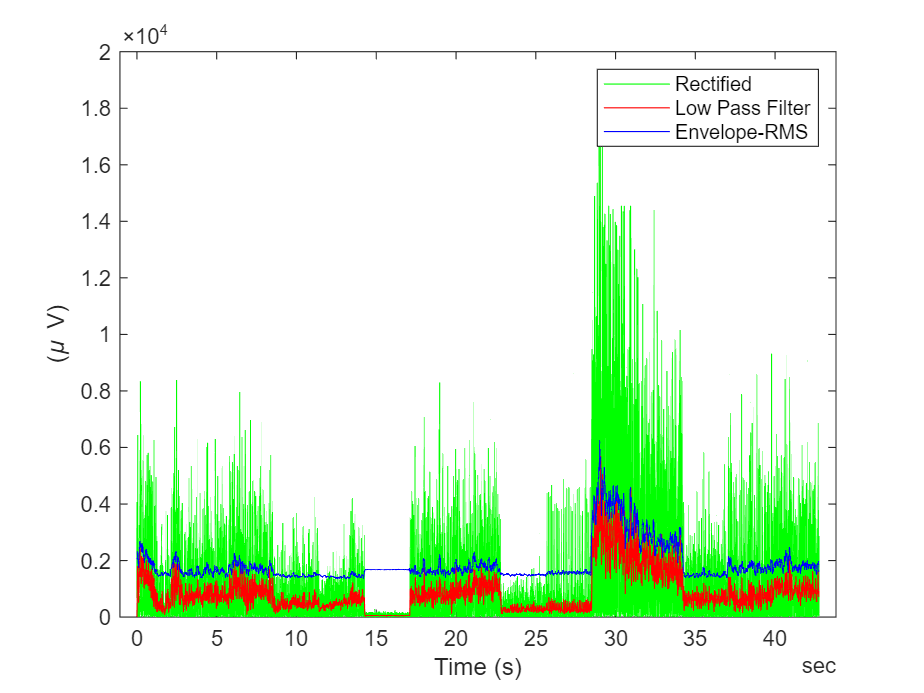

clf
plot(t,rec_data(:,1),'g',t,env1(:,1),'r',t,env2(:,1), 'b');
xlabel('Time (s)'); 
ylabel('(\mu V)');
legend('Rectified','Low Pass Filter', 'Envelope-RMS');

## Other Features

Let's consider the frequency domain. Some other common parameters used in EMG analysis are 

- Amplitude Parameters - peak EMG value, mean EMG value, area under the EMG amplitude (mathematical integral)

- Frequency Parameters - peak power, total power (area under the spectrum curve), mean frequency, median frequency

**Total Power Calculation**

Let's try getting total power as a feature. 

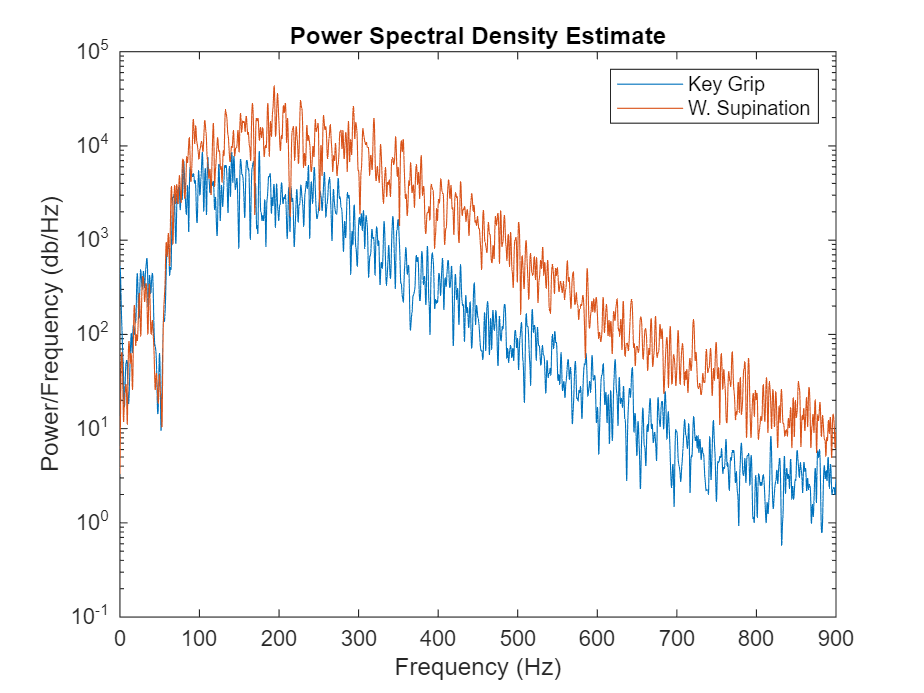

clf
[pxx,f] = pspectrum([keygrip,wsupination],fs);
semilogy(f,pxx)
title('Power Spectral Density Estimate')
ylabel('Power/Frequency (db/Hz)')
xlabel('Frequency (Hz)')
legend('Key Grip','W. Supination')

totalpower = trapz(f,pxx,1);
fprintf('Total power in key grip signal is %.3e.\n',totalpower(1))

Total power in key grip signal is 8.699e+05.


fprintf('Total power in w. supination signal is %.3e.\n',totalpower(2))

Total power in w. supination signal is 3.594e+06.


## Train Classifier

Now that we've looked at more specific features, let's train our machine learning model. There are many features from time and frequency domain we can exploit as predictors for the EMG signal. For now, let's use the **envelope** we calculated before, **signal variance**, and **total power** under the spectrum curve.  Open [generateFeatures](matlab: edit generateFeatures) to examine the code.

funs = @(x)generateSignalFeatures(x,fs);
traindataSP = blockproc(TrainData{:,1:nsensors},[blocksize nsensors],@(block)funs(block.data));
traindataSP = array2table(traindataSP);
traindataSP.Properties.VariableNames = makeVariableNames({'var';'env';'tpwr'}, nsensors);
traindataSP.Action = TrainData.Action(1:blocksize:end);

Now that we have our features for training, the next step is to choose a machine learning algorithm. Which type of classifier will work best in this case? We will use the Classification Learner App to explore various algorithms until we find one that yields satisfactory results.

`classificationLearner`

An added benefit in using the Classification Learner is that it can generate the MATLAB code to retrain the model or incorporate new data.  Below, we use the generated code from the classification learner to calculate the validation accuracy.  In this case, we use 5-fold cross-validation.

[classifier, validationAccuracy] = trainSPClassifier(traindataSP);

disp(['Accuracy is ', num2str(validationAccuracy * 100) ,'%'])

Accuracy is 93.4815%


## Make Predictions on Test Set

Now that we have a trained classifier, it can be used to make predictions on the independent test set from another experiment.

Apply all of the same preprocessing steps to the new data.

testds = datastore(fullfile(strcat(dataPath,'/Data/TestingData/*.csv')));
testds.SelectedFormats{9} = '%C';
TestData = readall(testds);
testdataSP = blockproc(TestData{:,1:nsensors},[blocksize nsensors],@(block)funs(block.data));

Then use the classifier to make predictions and compare to known results.

[PredictedAction,score] = predict(classifier.ClassificationEnsemble,testdataSP);
disp("Accuracy is " + nnz(PredictedAction==TestData.Action(1:blocksize:end))./numel(PredictedAction)*100 + "%")

Accuracy is 79.2593%


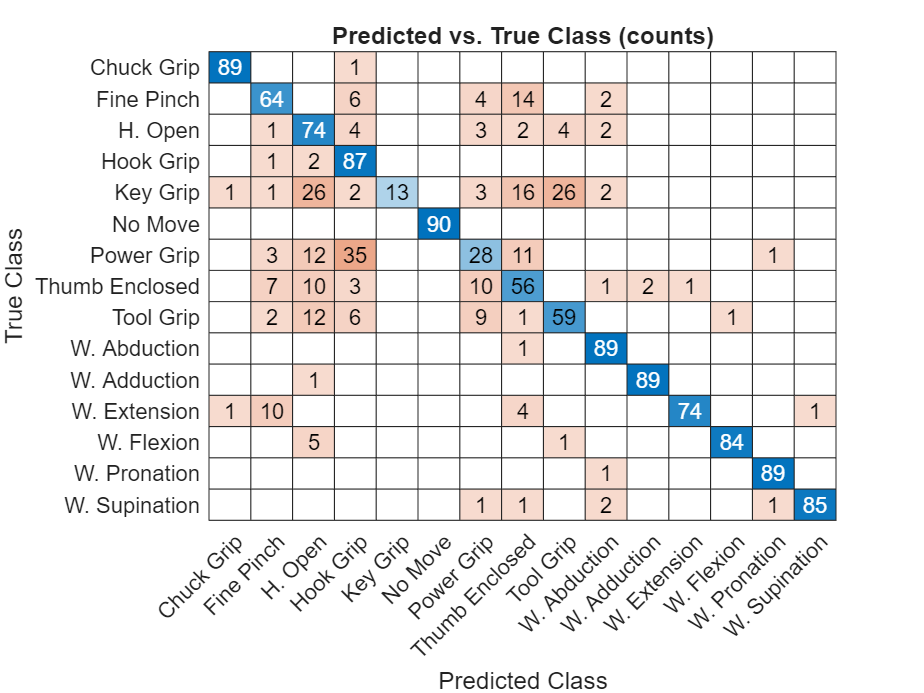

confusionchart(TestData.Action(1:blocksize:end), PredictedAction);
title("Predicted vs. True Class (counts)")

## Model Refinement: Number of Trees

How many trees do we really need? The model provides an out-of-bag loss function for calculating how much more error there is by leaving out additional trees

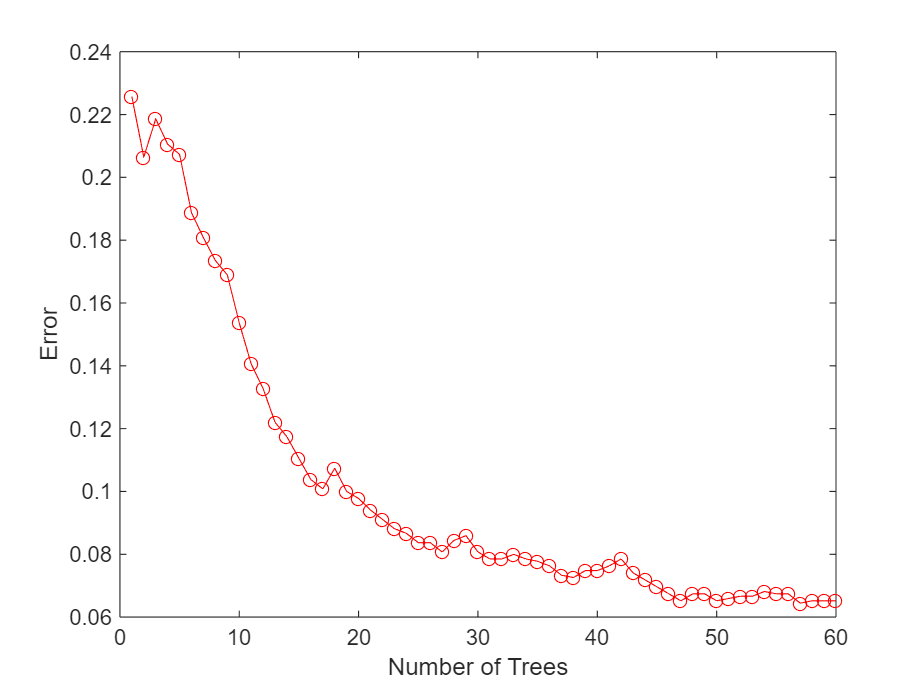

plot(oobLoss(classifier.ClassificationEnsemble,'mode','cumulative'),'ro-')
xlabel('Number of Trees')
ylabel('Error')

## Model Refinement: Predictor Importance

Which predictors are the most important to the model? The `predictorImportance` metric tells us how the error would change if that predictor were removed.

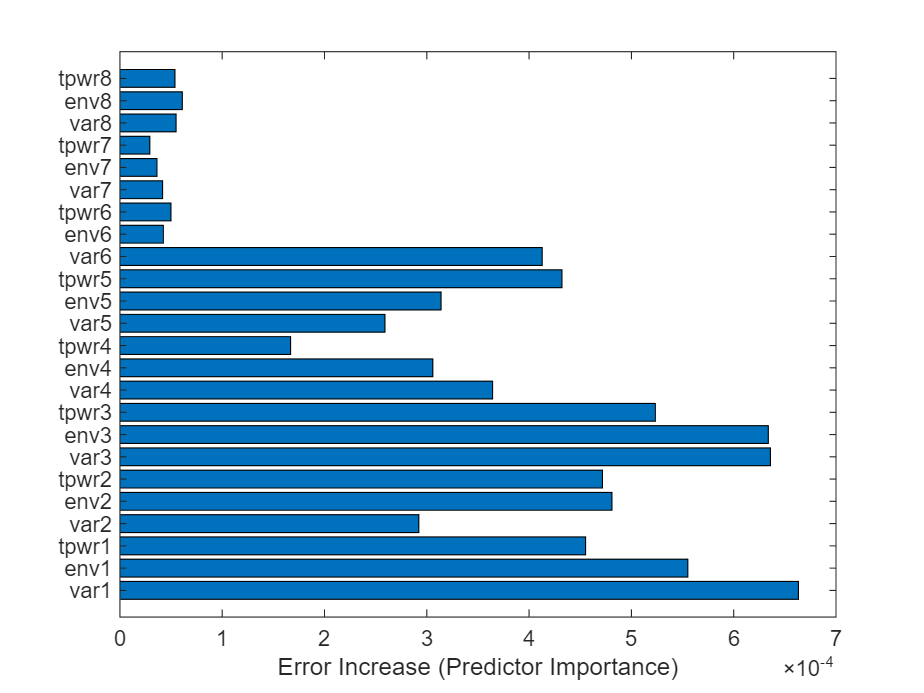

predimp = predictorImportance(classifier.ClassificationEnsemble);
barh(predimp)
ax = gca;
ax.YTick = 1:numel(predimp);
ax.YTickLabel = classifier.RequiredVariables;
xlabel('Error Increase (Predictor Importance)')

## Use the Classifier

Let's package up the classifier into a function that takes raw signal data from our 8 channels and outputs a classification for that chunk of signal.

x = TestData{1:57,1:nsensors};
classifyEMGSignal(x,fs)

ans = 'Chuck Grip'

*Copyright 2025 The MathWorks, Inc.*